**Statistical Methods **

**Luis Mario Bres Castro**

**Lab 6: Amplitude Modulated Sinosoid Signal **

**Time-Frequency transform: Spectogram**

pmlibRootDir = '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods';
addpath(genpath(pmlibRootDir),"-begin");
%Signal Parameters
A=10; 
f0=150; 
f1=4;
psi0=0;

%Time samples 

%Instantaneous phase
%I(t)=2*pi*f0*t
%dI/dt=f0

maxFreq = f0;
samplFreq = 5*maxFreq;
samplIntrvl = 1/samplFreq;

% Time samples
t = 0:samplIntrvl:2.0;
% Number of samples
nSamples = length(t);
%Generate Signal
SigVec = AMSigGen(t,A,f0,f1,psi0);
plot(t,SigVec)
title('Time signal of AM Modulation')
xlabel('Time [s]')
ylabel('Amplitude')

%Length of data 
dataLen = t(end)-t(1);
%DFT sample corresponding to Nyquist frequency
kNyq = floor(nSamples/2)+1;
% Positive Fourier frequencies
posFreq = (0:(kNyq-1))*(1/dataLen);
% FFT of signal
fftSig = fft(SigVec);
% Discard negative frequencies
fftSig = fftSig(1:kNyq);
figure;
plot(posFreq,abs(fftSig));
title('Periodogram of AM Signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

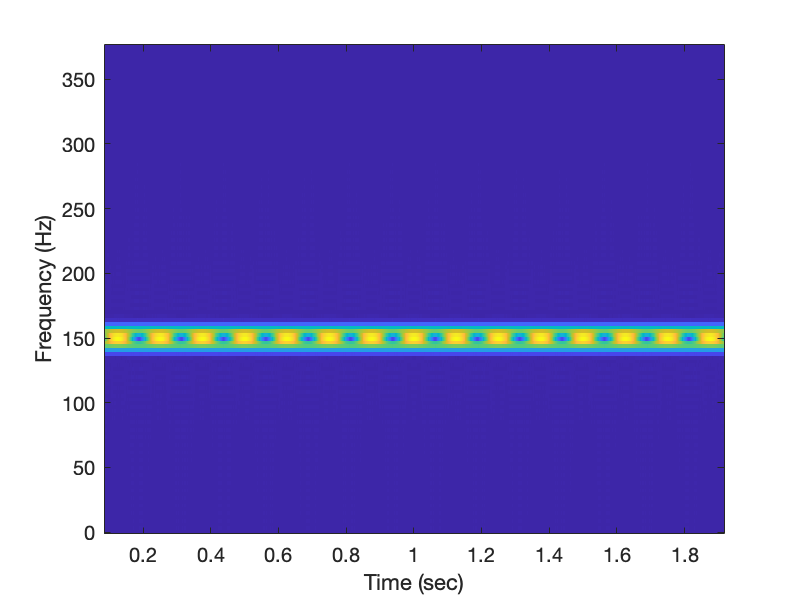

%Plot a spectrogram
%From testcrcbgenqcsig.m
[S,F,T]=spectrogram(SigVec,128,127,[],samplFreq);
figure;
imagesc(T,F,abs(S)); axis xy;
xlabel('Time (sec)');
ylabel('Frequency (Hz)');
title('Spectogram of AM Signal')